Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:05 |       28.12% |       1.8308 |          0.0100 |
|       1 |          50 |       00:00:13 |       92.19% |       0.3580 |          0.0100 |
|       1 |         100 |       00:00:22 |       96.88% |       0.1999 |          0.0100 |
|       2 |         150 |       00:00:30 |       93.75% |       0.2270 |          0.0100 |
|       2 |         200 |       00:00:38 |       90.62% |       0.3371 |          0.0100 |
|       3 |         250 |       00:00:46 |       89.06% |       0.2109 |          0.0100 |
|       3 |         300 |       00:00:53 |       93.75% |       0.

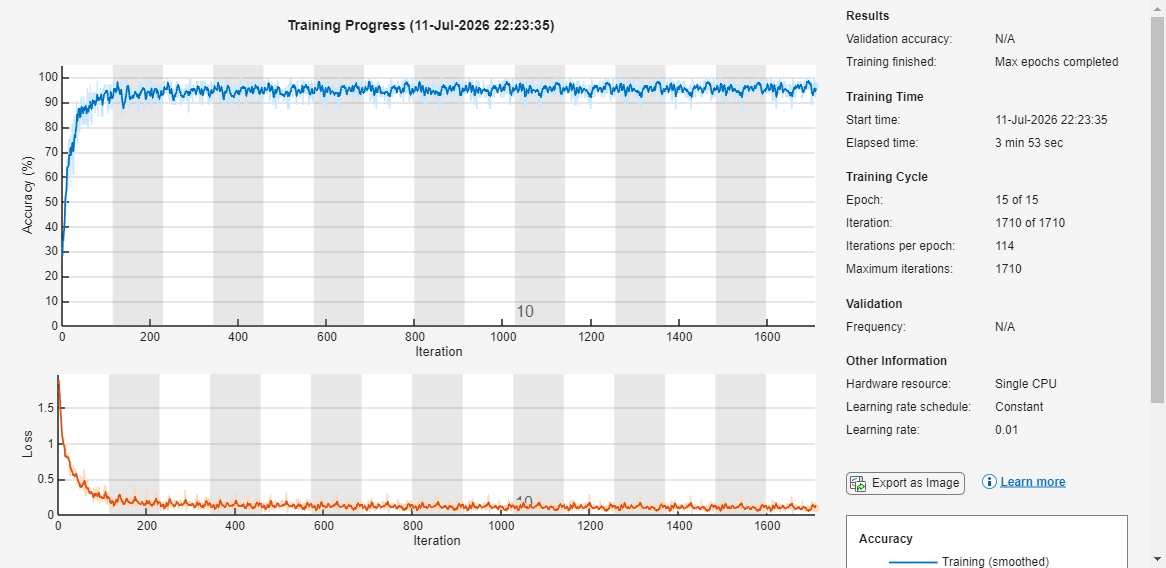

%% Human Activity Recognition using 1D-CNN (Multi-Channel IMU)
% Author: Bhogala Srika
% Project: MathWorks Challenge - HAR Model
% Description: Trains a 1D-CNN on all 9 inertial signal channels
% (body_acc, body_gyro, total_acc x/y/z) to classify human movement.

clear; clc; close all;

%% 1. Load Data — all 9 signal channels
signalNames = {'body_acc_x','body_acc_y','body_acc_z', ...
               'body_gyro_x','body_gyro_y','body_gyro_z', ...
               'total_acc_x','total_acc_y','total_acc_z'};

numChannels = numel(signalNames);

trainDir = fullfile('..','data','UCI HAR Dataset','train','Inertial Signals');
testDir  = fullfile('..','data','UCI HAR Dataset','test','Inertial Signals');

trainLabelPath = fullfile('..','data','UCI HAR Dataset','train','y_train.txt');
testLabelPath  = fullfile('..','data','UCI HAR Dataset','test','y_test.txt');

labelsTrain = readmatrix(trainLabelPath);
labelsTest  = readmatrix(testLabelPath);

numTrainObs = size(labelsTrain, 1);
numTestObs  = size(labelsTest, 1);
seqLength   = 128;

% Preallocate: [observations x channels x timesteps]
rawTrain = zeros(numTrainObs, numChannels, seqLength);
rawTest  = zeros(numTestObs, numChannels, seqLength);

for c = 1:numChannels
    trainFile = fullfile(trainDir, [signalNames{c} '_train.txt']);
    testFile  = fullfile(testDir,  [signalNames{c} '_test.txt']);

    rawTrain(:, c, :) = readmatrix(trainFile);
    rawTest(:, c, :)  = readmatrix(testFile);
end

%% 2. Preprocessing — normalize each channel using training statistics
mu  = mean(rawTrain, [1 3]);   % mean per channel
sig = std(rawTrain, 0, [1 3]); % std per channel

rawTrain = (rawTrain - mu) ./ sig;
rawTest  = (rawTest - mu) ./ sig;

% Convert to cell array of [numChannels x seqLength] sequences
XTrain = cell(numTrainObs, 1);
for i = 1:numTrainObs
    XTrain{i} = squeeze(rawTrain(i, :, :));
end

XTest = cell(numTestObs, 1);
for i = 1:numTestObs
    XTest{i} = squeeze(rawTest(i, :, :));
end

YTrain = categorical(labelsTrain);
YTest  = categorical(labelsTest);

%% 3. Model Architecture
layers = [
    sequenceInputLayer(numChannels, 'MinLength', seqLength)

    convolution1dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    convolution1dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling1dLayer(2)
    dropoutLayer(0.2)

    globalAveragePooling1dLayer
    fullyConnectedLayer(32)
    reluLayer

    fullyConnectedLayer(6)
    softmaxLayer
    classificationLayer];

%% 4. Training Options
options = trainingOptions('sgdm', ...
    'MaxEpochs', 15, ...
    'MiniBatchSize', 64, ...
    'InitialLearnRate', 0.01, ...
    'Plots', 'training-progress', ...
    'Verbose', true);

net = trainNetwork(XTrain, YTrain, layers, options);


%% 5. Evaluation
YPred = classify(net, XTest);
accuracy = sum(YPred == YTest) / numel(YTest);

fprintf('Final Model Accuracy: %.2f%%\n', accuracy * 100);

Final Model Accuracy: 91.92%


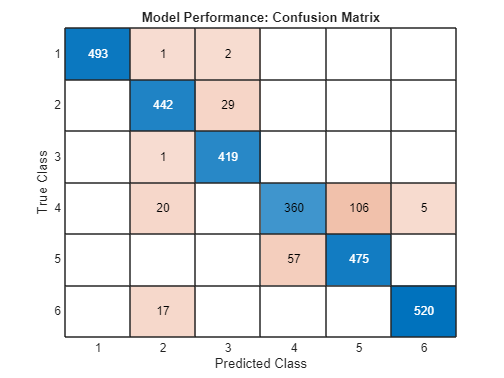


% Confusion Matrix
figure;
confusionchart(YTest, YPred);
title('Model Performance: Confusion Matrix');


%% 6. Save trained model (for reuse / verification script)
save(fullfile('..','models','trained_net.mat'), 'net', 'mu', 'sig');